# MECH 6323 - Homework 3

Author: Jonas Wanger

Date: 2022-03-01

clear
close all

## Problem 2

#### System Definition

% System Matrices
A = [-2  5;
     -5 -3];
B = [-2  4;
     -2 -2];
C = [ 1  2;
     -4  3];
D = zeros(2);
% State Space Model
sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2
   x1  -2   5
   x2  -5  -3
 
  B = 
       u1  u2
   x1  -2   4
   x2  -2  -2
 
  C = 
       x1  x2
   y1   1   2
   y2  -4   3
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



% Transfer Function
sys_tf = tf(sys)

sys_tf =
 
  From input 1 to output...
          -6 s - 4
   1:  --------------
       s^2 + 5 s + 31
 
          2 s + 82
   2:  --------------
       s^2 + 5 s + 31
 
  From input 2 to output...
            -46
   1:  --------------
       s^2 + 5 s + 31
 
         -22 s - 80
   2:  --------------
       s^2 + 5 s + 31
 
Continuous-time transfer function.



% ZPK Model
sys_zpk = zpk(sys)

sys_zpk =
 
  From input 1 to output...
        -6 (s+0.6667)
   1:  ---------------
       (s^2 + 5s + 31)
 
          2 (s+41)
   2:  ---------------
       (s^2 + 5s + 31)
 
  From input 2 to output...
             -46
   1:  ---------------
       (s^2 + 5s + 31)
 
        -22 (s+3.636)
   2:  ---------------
       (s^2 + 5s + 31)
 
Continuous-time zero/pole/gain model.



### Part a - Stability

The stability of the internal system $P$ (unforced) can be determined based on the eigen values of $A$ and ensuring $\mathbb{Re}(\lambda_i) < 0 \ \forall_{i=1,\dots,n}$.

P_poles = eig(A)

P_poles =   -2.5000 + 4.9749i
  -2.5000 - 4.9749i


Thidxs result demonstrates that the system is indead stable with underdamped poles at $\lambda_{1,2} = -2.50 \pm j 4.98$.

This gaurentees asymptotic stability of the system as well as BIBO stability.

### Part b - $H_\infty$-norm

% H_\infty calc
[P_inf_norm, omega_p] = hinfnorm(sys)

P_inf_norm = 6.5024

omega_p = 4.9703

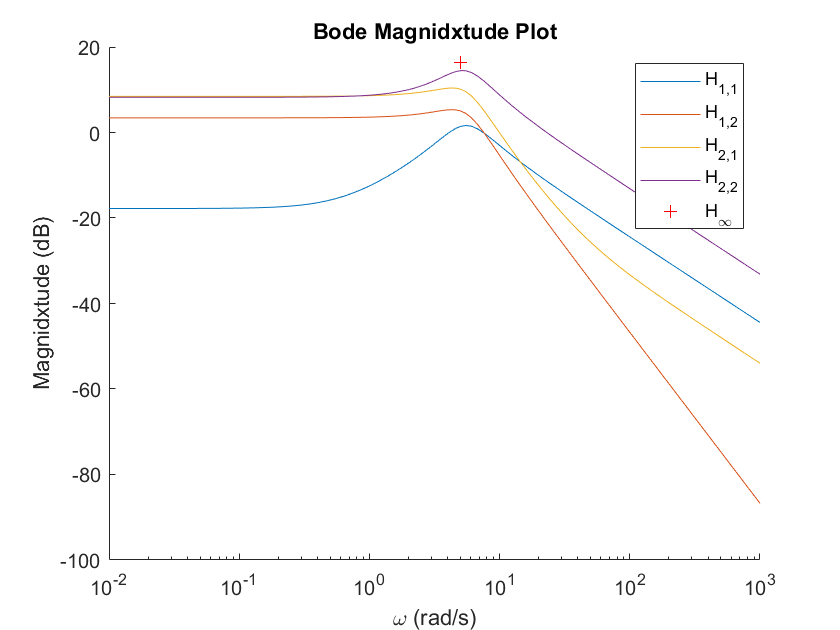

% Bode Data
[mag, phase, wout] = bode(sys);
% Plot Bode mag on one plot
figure
hold on
for idx_1 = 1:2
    for idx_2 = 1:2
        plot(wout,reshape(mag2db(mag(idx_1,idx_2,:)),1,[]), 'DisplayName',['H_{',num2str(idx_1),',',num2str(idx_2),'}'])
    end
end
plot(omega_p, mag2db(P_inf_norm),'+r', 'DisplayName', 'H_{\infty}')
set(gca, 'XScale', 'log')
title('Bode Magnidxtude Plot')
xlabel('\omega (rad/s)')
ylabel('Magnidxtude (dB)')
legend()

### Part c - SVD

% H_peak calc
H_peak = evalfr(sys,1i*omega_p)

H_peak =   -1.1659 - 0.1345i  -0.4407 + 1.7394i
   1.1615 - 3.0054i  -4.9010 + 1.9774i


H_peak_svd = svd(H_peak)

H_peak_svd =     6.5024
    0.7918


Clearly they match.

## Part d - Sigma plot

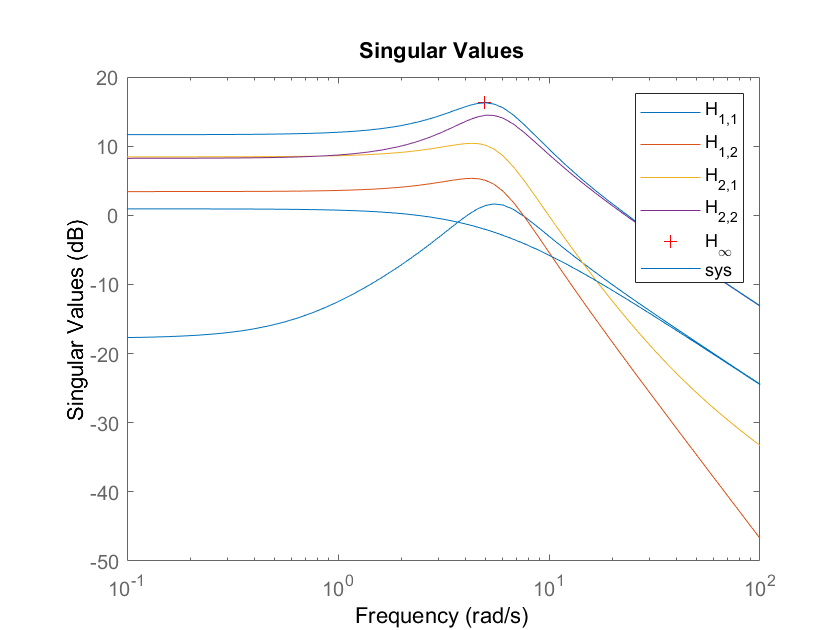

% Plot Sigma
sigma(sys)

Clearly they match.

## Part e - SVD I/O Calc

% SVD Calc
[U,S,V] = svd(H_peak)

U =   -0.2373 - 0.1974i   0.5432 - 0.7808i
   0.2847 - 0.9075i  -0.3014 - 0.0667i


S =     6.5024         0
         0    0.7918


V =    0.5170 + 0.0000i  -0.8560 + 0.0000i
  -0.5273 + 0.6743i  -0.3185 + 0.4072i


% Maximum vectors
U_max = U(:,1);
V_max = V(:,1);
% I/O Coeficient Vectors
a = abs(V_max)

a =     0.5170
    0.8560


phi = angle(V_max) - pi/2

phi =    -1.5708
    0.6637


b = S(1,1) * abs(U_max)

b =     2.0074
    6.1848


psi = angle(U_max) - pi/2

psi =    -4.0185
   -2.8376


% norm gain check
IO_norm_gain = norm(b)/norm(a)

IO_norm_gain = 6.5024

## Part f - Simulate System

%% Sim Setup
dt = 0.1;
tf = 5;
t = 0:dt:tf;

%% Input/Output Production
u = a .*  sin(omega_p * t + phi)

u =    -0.5170   -0.4544   -0.2819   -0.0412    0.2095    0.4095    0.5104    0.4878    0.3471    0.1225   -0.1318   -0.3542   -0.4909   -0.5088   -0.4035   -0.2006    0.0508    0.2900    0.4589    0.5169    0.4497    0.2737    0.0315   -0.2183   -0.4153   -0.5118   -0.4845   -0.3399   -0.1130    0.1412    0.3612    0.4938    0.5070    0.3974    0.1917   -0.0604   -0.2979   -0.4633   -0.5166   -0.4449   -0.2655   -0.0219    0.2271    0.4210    0.5131    0.4810    0.3325    0.1036   -0.1504   -0.3681
    0.5273    0.7850    0.8528    0.7142    0.4027   -0.0062   -0.4136   -0.7209   -0.8538   -0.7800   -0.5175   -0.1298    0.2894    0.6385    0.8331    0.8261    0.6192    0.2625   -0.1578   -0.5399   -0.7913   -0.8512   -0.7052   -0.3885    0.0222    0.4275    0.7294    0.8548    0.7733    0.5047    0.1139   -0.3044   -0.6490   -0.8366   -0.8218   -0.6080   -0.2472    0.1735    0.5522    0.7973    0.8494    0.6960    0.3742   -0.0382   -0.4413   -0.7377   -0.8555   -0.7663   -0.4916   -0

y = b .* sin(omega_p * t + psi)

y =     1.5432    0.7443   -0.2347   -1.1569   -1.7992   -2.0060   -1.7274   -1.0308   -0.0848    0.8818    1.6350    1.9925    1.8679    1.2912    0.4021   -0.5843   -1.4293   -1.9285   -1.9609   -1.5189   -0.7093    0.2720    1.1874    1.8155    2.0043    1.7080    0.9984    0.0472   -0.9154   -1.6565   -1.9967   -1.8538   -1.2623   -0.3653    0.6201    1.4555    1.9386    1.9526    1.4941    0.6740   -0.3092   -1.2175   -1.8312   -2.0018   -1.6880   -0.9657   -0.0097    0.9487    1.6774    2.0003
   -1.8515   -4.4412   -5.9562   -6.0298   -4.6443   -2.1349    0.8912    3.7015    5.6162    6.1718    5.2338    3.0293    0.0918   -2.8680   -5.1337   -6.1571   -5.6906   -3.8470   -1.0724    1.9616    4.5210    5.9863    6.0030    4.5670    2.0259   -1.0055   -3.7936   -5.6637   -6.1632   -5.1712   -2.9279    0.0239    2.9700    5.1973    6.1670    5.6443    3.7557    0.9583   -2.0711   -4.5992   -6.0144   -5.9741   -4.4882   -1.9162    1.1196    3.8844    5.7092    6.1524    5.1068    2

#### Simulate System

ysim = lsim(sys,u,t)';

#### Plot Sim

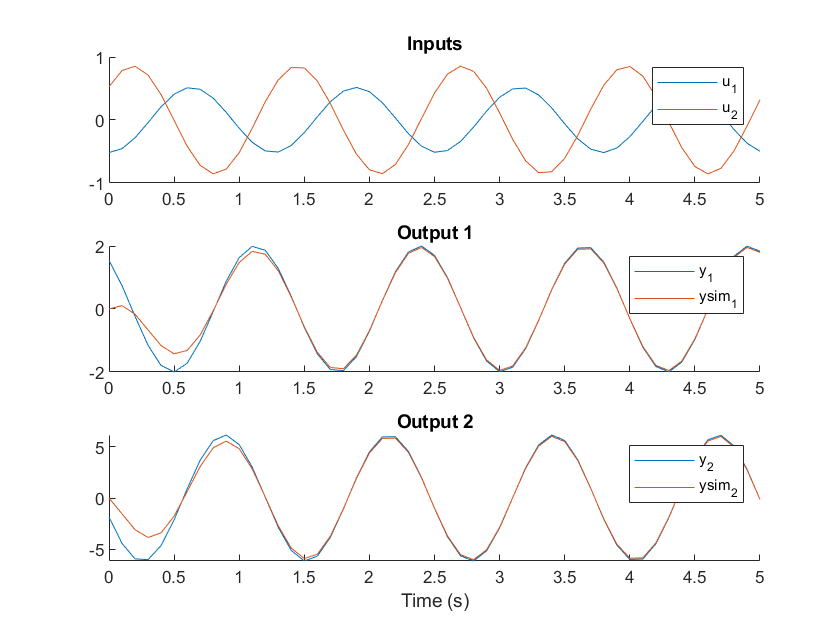

figure
% Plot Inputs
subplot(3,1,1)
hold on
plot(t,u(1,:),'DisplayName','u_1')
plot(t,u(2,:),'DisplayName','u_2')
legend()
title('Inputs')
% Plot Outputs
for idx = 1:2
    subplot(3,1,idx+1)
    hold on
    plot(t,y(idx,:),'DisplayName',['y_',num2str(idx)])
    plot(t,ysim(idx,:),'DisplayName',['ysim_',num2str(idx)])
    legend()
    title(['Output ',num2str(idx)])
end
xlabel('Time (s)')

It is evident that works.